# FMCW Radar Lab: Doppler Response vs. Time

This script demonstrates how we can visualize the Doppler response for an FMCW radar as a function of time to chracterize how objects are moving at certain ranges.

## System Setup

Before going through the lab, we prepare the workspace by clearing variables, closing figures, suppressing warnings.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin')

For this lab, we use many of the same parameters that were used in lab 1.

We set the center frequency to 10 GHz.

fc = 10e9;

The PRF will impact the maximum radial target velocity that we can observe unambiguously when performing Doppler processing. If we send out pulses more frequently, we will be able to observe targets moving with higher velocities. If we send out pulses less frequenctly, targets with high velocities will alias into the lower frequency Doppler region. Try changing the PRF to see the effect that it has.

prf = 1000;

The number of pulses that we process together will impact the Doppler resolution and gain when performing Doppler processing. With more pulses, we are able to resolve a targets velocity more clearly and we get more processing gain. Try changing the number of pulses to see the effect that it has.

nPulses = 80;

We set the sampling rate to be 1 MHz.

fs = 1e6;

We set the ramp bandwidth of the system to be 500 MHz.

rampbandwidth = 500e6;

Finally, we set up the FMCW radar with these key system parameters. Each of the outputs of the function below are responsible for controlling some part of the radar.

[rx,tx,bf,bf_TDD] = setupLabRadar(fc,prf,nPulses,fs,rampbandwidth);

## Data Collection

With our FMCW radar configured. It is time to capture some radar data and visualize the Doppler vs. time data.

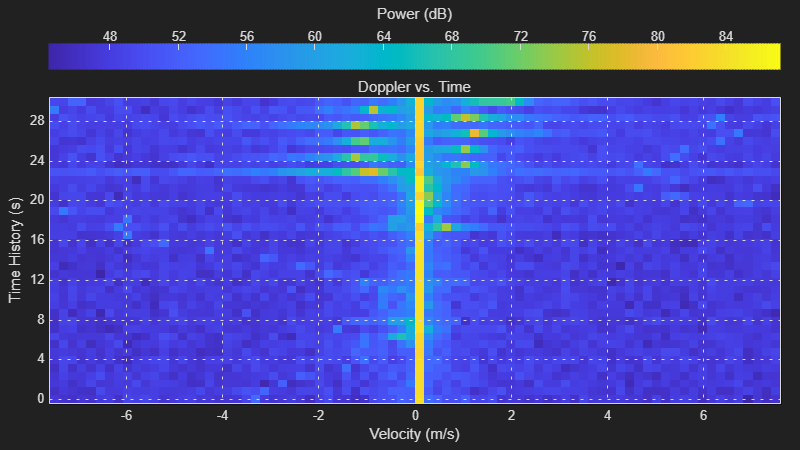

% Run time in seconds
tCapture = 30;

% Get the min and max ranges to include on the plot
minRange = 0;
maxRange = 10;

% Create a range-Doppler response for processing data
tSweep = double(bf.FrequencyDeviationTime)/1e6;
sweepSlope = rampbandwidth/tSweep;
rd = phased.RangeDopplerResponse(DopplerOutput="Speed",OperatingFrequency=fc,SampleRate=fs,RangeMethod="FFT",SweepSlope=sweepSlope,PRFSource="Property",PRF=prf);

% Adjustment factor to account for processing time, this is jsut to control time resolution on display
tAdjust = 10;

% Frequency difference between points in the Doppler domain. 
df = prf/(nPulses-1); 

% Setup the DTI scope to plot Doppler vs. Time
dtiscope = phased.DTIScope(IQDataInput=false,DopplerOutput='Speed',DopplerOffset=-prf/2,DopplerResolution=df,TimeSpan=tCapture,TimeResolution=1/prf*nPulses*tAdjust,OperatingFrequency=fc);

% Capture the first waveform which typically has 0 values
captureTransmitWaveform(rx,tx,bf);

t = tic;
while toc(t) < tCapture
    % capture data
    data = captureTransmitWaveform(rx,tx,bf);

    % Arrange data into pulses
    data = arrangePulseData(data,rx,bf,bf_TDD);

    % Get the response
    [resp,range,speed] = rd(data);

    % Get range of interest - average data over this range
    keepRange = range >= minRange & range <= maxRange;
    resp = mean(abs(resp(keepRange,:)),1);

    % Plot data
    dtiscope(resp');
end


% Disable TDD Trigger
cleanupAntenna(rx,tx,bf,bf_TDD);